# Rovnice 3D kvadrokoptery se zavazim + kontrola riditelnosti a pozorovatelnosti (verze jine uhly)

*01.03.2025*

### Predpoklady

- kvadrotor je v konfiguraci X a je tuhe symetricke teleso

- lano (kabel) je nehmotne

- neuvazujeme odpor vzduchu

- zavazi povazujeme za hmotny bod (presto musim pouzit setrvacnost v rovnici...)

- lano je nepruzne a ma konstantni delku

- lano je spojeno s hmotnym stredem kvadrokoptery

- kazdy motor ma stejny tahovy a momentovy koeficient

- parametry soustavy se nemeni s casem

### Elementarni matice rotace

Pouzivam konvenci rotace **YZX** na ulhy yaw, pitch, roll 

syms phi(t) theta(t) psi(t) % roll, pitch, yall

R_x = [1, 0, 0; 
       0, cos(phi), -sin(phi);
       0, sin(phi), cos(phi)];

R_y = [cos(theta), 0, sin(theta); 
       0, 1, 0; 
      -sin(theta), 0, cos(theta)];

R_z = [cos(psi), -sin(psi), 0; 
       sin(psi), cos(psi), 0; 
       0, 0, 1];

% Celkova matice rotace ZYX (yaw->pich->roll)
Rzyx = R_z*R_y*R_x;

### Matice pro transformaci derivací Eulerových úhlů na vektor úhlové rychlosti v soustavě těla:

% potvrzuji tyto zdroje
% https://www.mathworks.com/help/symbolic/derive-quadrotor-dynamics-for-nonlinearMPC.html
% https://ieeexplore.ieee.org/document/9836215

Wzyx = [1 0 -sin(theta); 
    0 cos(phi) cos(theta)*sin(phi);
    0 -sin(phi) cos(theta)*cos(phi)];

### **Promenne a parametry**

6 DOF kopter + 2 DOF zavazi = 8 DOF

syms x(t) y(t) z(t) phi(t) theta(t) psi(t) % kopter
syms alpha(t) beta(t) % zmena uhlu, v tomto odvozeni jsou to jine uhly
% z obrazku: theta -> alpha(t), fi -> beta(t)

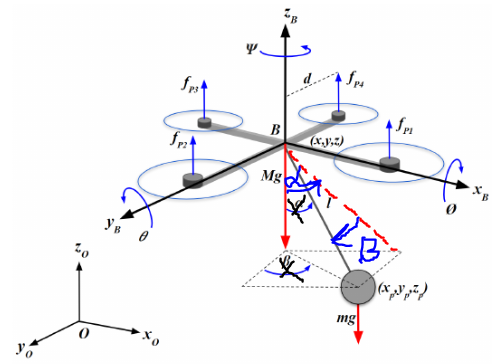

Orientacni konfigurace, `alfa(t)` je mezi projekci lana v rovine a osou z, `beta(t)` je mezi projekci lana v rovine a lanem v prostoru


syms T Tau_phi Tau_theta Tau_psi % vstupy
syms M m g Ixx Iyy Izz Ip d
% d - delka lana
I = [Ixx, 0, 0;
     0, Iyy, 0;
     0, 0, Izz];

### Lagrangian


$$\begin{array}{l}
\frac{d}{\textrm{dt}}\left(\frac{\partial \textrm{Lag}}{\partial \overset{\cdot }{q} }\right)-\frac{\partial \textrm{Lag}}{\partial q}=Q^{\textrm{nc}} ,\textrm{kde}\\
\textrm{Lag}=E_k -E_p 
\end{array}$$


Kineticka energie kvadrokoptery:

% translacni
Ek1 = 1/2*M*(diff(x,1)^2 + diff(y,1)^2 + diff(z,1)^2);

% rotacni

Co je J? "...is the Jacobian matrix expressing the moment of inertia in the inertial reference frame..." [https://ieeexplore.ieee.org/document/9836215](https://ieeexplore.ieee.org/document/9836215)

J = transpose(Wzyx)*I*Wzyx;
eta = [phi; theta; psi];
Ek2 = 1/2*transpose(diff(eta,1))*J*diff(eta,1);


Kineticka energie zavazi:

% translacni
% souradnice zavazi v inercialni soustave (TADY ZMENA!!!)
% x_d = x + d*sin(alpha)*cos(beta);
% y_d = y + d*sin(alpha)*sin(beta);
% z_d = z - d*cos(alpha);

% ted popis podle tohoto obrazku 
% https://link.springer.com/article/10.1007/s11071-023-08269-1#Equ1

x_d = x + d*cos(beta)*sin(alpha);
y_d = y + d*sin(beta);
z_d = z - d*cos(beta)*cos(alpha);


Ek3 = 1/2*m*(diff(x_d,1)^2 + diff(y_d,1)^2 + diff(z_d,1)^2);

% rotacni //спорно//
% Ek4 = 1/2*Ip*(diff(alpha,1)^2 + diff(beta,1)^2);
Ek4=0;

Celkova kineticka energie:

Ek = Ek1+Ek2+Ek3+Ek4;

Potencialni energie soustavy:

Ep = M*g*z + m*g*z_d;

Nekonzervativni smery:

Qnc = [Rzyx*[0;0;T]; Tau_phi; Tau_theta; Tau_psi; 0; 0];
% dve posledni 0 znamenaji, ze na zavazi nepusobi zadne vnejsi nekonz sily

#### Derivace a odvozeni:

q = [x y z phi theta psi alpha beta];
q_dot = diff(q);
Lag = expand(Ek-Ep);

% dLagdq = transpose(jacobian(Lag, q));
% 
% dLagdqdot = transpose(jacobian(Lag, q_dot));
% ddLagdqdotdt = diff(dLagdqdot, 1);
% 
% eq = formula(ddLagdqdotdt) - formula(dLagdq) == formula(Qnc);
% % pro lepsi prehlednost
% eq_t = subsStateVars(eq);

eq = transpose(diff(jacobian(Lag, q_dot), 1)) - transpose(jacobian(Lag, q)) == Qnc;
eq_t = subsStateVars(eq)

### Maticovy tvar


$$M\left(q\right)\cdot \overset{\cdot \cdot }{q} +\left(C+G\left(\overset{\cdot }{q} \right)\right)\cdot \overset{\cdot }{q} +Q\left(q\right)=L\left(q\right)\cdot u$$


% zobecnene promenne
q = transpose([x y z phi theta psi alpha beta]);
q_dot = diff(q);
q_ddot = diff(q_dot);

% zobecnene promenne ve tvaru ..._t
q = subsStateVars(q);
q_dot = subsStateVars(q_dot);
q_ddot = subsStateVars(q_ddot);

% Matice hmotnosti a setrvacnosti
[MM, zbytek] = equationsToMatrix(eq_t, q_ddot);
MM = simplify(MM);

% Matice Coriolisovych sil a treni (odpor vzduchu)
[C_G, zbytek2] = equationsToMatrix_abatea(-1*zbytek, q_dot);

% Matice vstupu a gravitace
inputs = [T; Tau_phi; Tau_theta; Tau_psi];
[L, Q] = equationsToMatrix_abatea(-1*zbytek2, inputs);
Q = -1*Q;


% Kontrola roznasobeni
eq_expand = expand(MM*q_ddot + C_G*q_dot + Q == L*inputs);
isAlways(eq_expand == eq_t) %--> super, takze matice jsou spravne

ans = 8×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1


Jak bude vypadat matice L pokud vstupy budou otacky rotoru?

syms l b_moment k_thrust
syms U1 U2 U3 U4 % Ui je wi^2 pro kazdy rotor dronu [ (rad/s)^2 ]

eqT = k_thrust*(U1+U2+U3+U4);
eqTau_phi = k_thrust*l*(U1+U4-U2-U3);
eqTau_theta = k_thrust*l*(U3+U4-U1-U2);
eqTau_psi = b_moment*(U1+U3-U2-U4);
% !!! Dulezitou podminkou je, ze hodnoty pouze Ui>=0

Lm = L*[eqT; eqTau_phi; eqTau_theta; eqTau_psi];
[Lm, ~] = equationsToMatrix(Lm, [U1 U2 U3 U4]);
% Lm*[U1;U2;U3;U4]

### Nelinearni State-Space model

% stavovy vektor X = [q; q_dot] -> 16 stavu

A = simplify( [zeros(8), eye(8); zeros(8), -inv(MM)*(C_G)]);
B = simplify([zeros(8,4); MM\L]);
BQ = [zeros(8,1); -MM\Q];

% Kontrola roznasobeni
% eq_ss = formula(A*[q; q_dot]+B*inputs+BQ);
% eq_ss = eq_ss(9:16);
% 
% eq_MM = MM\(L*inputs - C_G*q_dot - Q);
% 
% % isAlways(eq_ss == eq_MM) % kontrola ekvivalence...
% isAlways(simplify(eq_MM) == simplify(eq_ss)) % uz lepe, ale pro chyba v 6?
% 
% % ---------------------------------------
% eq6_1 = formula(simplify(eq_MM));
% eq6_1 = simplify(expand(eq6_1(6)));
% 
% eq6_2 = formula(simplify(eq_ss));
% eq6_2 = simplify(expand(eq6_2(6)));
% 
% isAlways(eq6_2 == eq6_1) % alespon nejak, doufam ze matlab nic nezkratil
% ---------------------------------------



$$\begin{array}{l}
\overset{\cdot }{X} =A\cdot X+B\cdot u+\textrm{BQ}\\
Y=X
\end{array}$$


Jak bude vypadat matice B, pokud budou vstupovat otacky rotoru?

% porovname 2 pristupy
Bmotors = B*[eqT; eqTau_phi; eqTau_theta; eqTau_psi];
[Bmotors, ~] = equationsToMatrix(Bmotors, [U1 U2 U3 U4]);
Bm = simplify([zeros(8,4); MM\Lm]); % Lm z maticoveho popisu
% Pokud udelam expand() a simplify(), tak Bmotors == Bm

### Linearizace a Linearni State-Space model

Rovnice prave strany


$$\overset{\cdot }{X} =f\left(X,U\right)$$


ff = [eye(8)*q_dot; MM\(L*inputs - C_G*q_dot - Q)];
% rovnice pravych stran

% vektor stavu
X = [q; q_dot];

%matice A (Jakobiho matice vuci stavum)
Aj = jacobian(ff, X);

%matice B (Jakobiho matice vuci vstupu)
Bj = jacobian(ff, inputs);

*Jakobiho matice pokud vstupy jsou druhe mocniny otacek rotoru:*

rotors = [U1;U2;U3;U4];
ffm = [eye(8)*q_dot; MM\(Lm*rotors - C_G*q_dot - Q)];

Amj = jacobian(ffm, X);
Bmj = jacobian(ffm, rotors);

Singularni bod

Xs = [0;0;0; 0;0;0; 0;0; 0;0;0; 0;0;0; 0;0]; % pro stavy
Us = [(M+m)*g; 0; 0; 0]; % pro vstupy
% Celkova takova sila Thrust rovna se tize, takze
% kvadrokoptera se zavazim zustavaji v rovnovaze

% singularni bod pro vstupy ve tvaru uhlovych rychlosti motoru
% --> pocitame otacky pro ustaleny stav dronu
wsquare = (M+m)*g/(4*k_thrust);
Uws = [wsquare; wsquare; wsquare; wsquare]; % w1^2, w2^2, w3^2, w4^2

Dosazeni singularnich bodu do Jacobianu

Ac = subs(Aj, [X; inputs], [Xs; Us]);
Ac = simplify(Ac)

$$Ac = \begin{array}{l} \left(\begin{array}{cccccccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & \sigma_{2} & 0 & \frac{g\,m}{M} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & -\sigma_{2} & 0 & 0 & 0 & \frac{g\,m}{M} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & -\sigma_{1} & 0 & -\sigma_{1} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & \sigma_{1} & 0 & 0 & 0 & -\sigma_{1} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{g\,\left(M+m\right)}{M\,d}\\ \sigma_{2}=\frac{g\,\left(M+m\right)}{M} \end{array}$$


Bc = subs(Bj, [X; inputs], [Xs; Us])

$$Bc = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ \frac{1}{M+m} & 0 & 0 & 0\\ 0 & \frac{1}{\mathrm{Ixx}} & 0 & 0\\ 0 & 0 & \frac{1}{\mathrm{Iyy}} & 0\\ 0 & 0 & 0 & \frac{1}{\mathrm{Izz}}\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

Pozor, dostavame model v nasledujicim tvaru:

$\Delta \overset{\cdot }{X} =A_c \cdot \Delta X+B_c \cdot \Delta u$, kde

$\Delta X=X-X_s$, $\Delta u=u-u_s$

*Linearni state-space pro vstupy ve tvaru druhych mocnin otacek rotoru:*

Amc = subs(Amj, [X; rotors], [Xs; Uws]);
Amc = simplify(Amc);

Bmc = subs(Bmj, [X; rotors], [Xs; Uws]);


#### **Kontrola stability, riditelnosti a pozorovatelnosti**

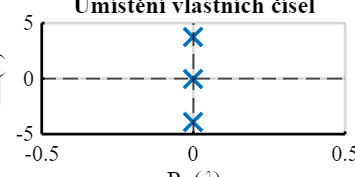

% take parametry nutne rucne menit
Ac = subs(Ac, [M Ixx Iyy Izz m d g], [2 0.0222 0.0222 0.0429 1 1 9.81]);
Bc = subs(Bc, [M Ixx Iyy Izz m d g], [2 0.0222 0.0222 0.0429 1 1 9.81]);

Ac = double(Ac); % a tohle uz muzeme analyzovat
Bc = double(Bc);
Cc = eye(8, 16); % na vystup pouze poloha, orientace a uhly zavazi

% vlastni cisla matici A
ev = eig(Ac);

figure;
set(gcf, 'Color', 'w', 'Units', 'centimeters', 'Position', [0 0 10 5]);
hold on
plot(real(ev), imag(ev), 'x', 'MarkerFaceColor', 'b', 'MarkerSize', 14, 'LineWidth', 2);
grid on;
xlabel('Re(\lambda)', 'FontSize', 14, 'FontName', 'Times New Roman');
ylabel('Im(\lambda)', 'FontSize', 14, 'FontName', 'Times New Roman');
title('Umístění vlastních čísel', 'FontSize', 14, 'FontName', 'Times New Roman');
yline(0, '--k', 'LineWidth', 1);
xline(0, '--k', 'LineWidth', 1);
xlim([-0.5, 0.5])
ylim([-5, 5])
hold off
set(gca, 'LineWidth', 1.5, 'FontSize', 12, 'XColor', 'k', 'YColor', 'k', 'FontName', 'Times New Roman')
ti = get(gca, 'TightInset');
set(gca, 'Position', [ti(1), ti(2), 1 - ti(1) - ti(3), 1 - ti(2) - ti(4)]);

% print(gcf, 'eig_pos', '-dsvg');

% Je system riditelny?
R = ctrb(Ac, Bc);
rank(R) % --> 16, je riditelny

ans = 16


% Je system pozorovatelny ?
P = obsv(Ac, Cc);
rank(P) % --> 16, je pozorovatelny

ans = 16

*Pokud vstupy jsou druhe mocniny otacek rotoru:*

Amc = subs(Amc, [M Ixx Iyy Izz m d g], [2 0.0222 0.0222 0.0429 1 1 9.81]);
Bmc = subs(Bmc, [M Ixx Iyy Izz m d g k_thrust b_moment l], [2 0.0222 0.0222 0.0429 1 1 9.81 9.3e-6 3.6e-7 0.2051]);
Amc = double(Amc);
Bmc = double(Bmc);

rank(ctrb(Amc, Bmc)) % --> 16, stale riditelny

ans = 16

P.S. Matice `Amc` a `Ac` jsou stejne, coz je logicky (a hlavne ze je overeno), protoze vztah mezi sily a otackami neovlivnuje dynamiku soustavy.

`Bmc` a `Bc` uz se lisi, protoze mame ruzne vstupy. Chci navrchout zesileni pomoci LQR pro Bmc a jeste ridit, aby hodnoty nebyly mensi nez 0.

### Ze stavoveho prostoru do prenosu

Cc = eye(8, 16);
sys = ss(Ac, Bc, Cc, 0);
sys_tf = tf(sys)


sys_tf =
 
  From input 1 to output...
   1:  0
 
   2:  0
 
       0.3333
   3:  ------
        s^2
 
   4:  0
 
   5:  0
 
   6:  0
 
   7:  0
 
   8:  0
 
  From input 2 to output...
   1:  0
 
       -662.8 s^2 - 6502
   2:  -----------------
        s^6 + 14.71 s^4
 
   3:  0
 
       45.05
   4:  -----
        s^2
 
   5:  0
 
   6:  0
 
   7:  0
 
            662.8
   8:  ---------------
       s^4 + 14.71 s^2
 
  From input 3 to output...
       662.8 s^2 + 6502
   1:  ----------------
       s^6 + 14.71 s^4
 
   2:  0
 
   3:  0
 
   4:  0
 
       45.05
   5:  -----
        s^2
 
   6:  0
 
           -662.8
   7:  ---------------
       s^4 + 14.71 s^2
 
   8:  0
 
  From input 4 to output...
   1:  0
 
   2:  0
 
   3:  0
 
   4:  0
 
   5:  0
 
       23.31
   6:  -----
        s^2
 
   7:  0
 
   8:  0
 
Continuous-time transfer function.


### Diskretizace linearniho systemu

% dis_sys = c2d(sys, 0.01);

#### Pomocne (lokalni) funkce nunte k vyjadreni matic pro pohybovou rovnici 

% https://stackoverflow.com/questions/42231714/matlab-equationstomatrix-for-nonlinear-equations/79263355#79263355

function [A,b] = equationsToMatrix_abatea( eq, x )
%EQUATIONSTOMATRIX equationsToMatrix_abatea for nonlinear equations
%   factors out the vector x from eq such that eq = Ax + b
%   eq does not need to be linear in x
%   eq must be a vector of equations, and x must be a vector of symbols

assert(isa(eq,'sym'), 'Equations must be symbolic')
assert(isa(x,'sym'), 'Vector x must be symbolic')

n = numel(eq);
m = numel(x);

A = repmat(sym(0),n,m);

for i = 1:n % loop through equations
    [c,p] = coeffs(eq(i),x); % separate equation into coefficients and powers of x(1)...x(n)
    for k = 1:numel(p) % loop through found powers/coefficients
        for j = 1:m % loop through x(1)...x(n)
            if has(p(k),x(j))
                % transfer term c(k)*p(k) into A, factoring out x(j)
                A(i,j) = A(i,j) + c(k)*p(k)/x(j);
                break % move on to next term c(k+1), p(k+1)
            end
        end
    end
end

b = simplify(eq - A*x,'ignoreanalyticconstraints',true); % makes sure to fully cancel terms
end


% https://www.mathworks.com/help/symbolic/derive-quadrotor-dynamics-for-nonlinearMPC.html
% Funkce pro zjednoduseni zapisu promennych s casem. x(t)-->x_t atd.
% Dela rovnice prehlednejsi (a zuzuje)

function stateExpr = subsStateVars(timeExpr,var)
    if nargin == 1 
        var = sym("t");
    end
    repDiff = @(ex) subsStateVarsDiff(ex,var);
    stateExpr = mapSymType(timeExpr,"diff",repDiff);
    repFun = @(ex) subsStateVarsFun(ex,var);
    stateExpr = mapSymType(stateExpr,"symfunOf",var,repFun);
    stateExpr = formula(stateExpr);
end

function newVar = subsStateVarsFun(funExpr,var)
    name = symFunType(funExpr);
    name = replace(name,"_Var","");
    stateVar = "_" + char(var);
    newVar = sym(name + stateVar);
end

function newVar = subsStateVarsDiff(diffExpr,var)
    if nargin == 1 
      var = sym("t");
    end
    c = children(diffExpr);
    if ~isSymType(c{1},"symfunOf",var)
      % not f(t)
      newVar = diffExpr;
      return;
    end
    if ~any([c{2:end}] == var)
      % not derivative wrt t only
      newVar = diffExpr;
      return;
    end
    name = symFunType(c{1});
    name = replace(name,"_Var","");
    extension = "_" + join(repelem("d",numel(c)-1),"") + "ot";
    stateVar = "_" + char(var);
    newVar = sym(name + extension + stateVar);
end